% Clearing
clc;
clear;

% Gettinga data
filename = "./Step2021-6x4x3.xlsx";
errikos_data = xlsread(filename, 1, "A2:H568");

time = errikos_data(:,1);
esc_signal = errikos_data(:,2);
throttle = errikos_data(:,3);
thrust_kgf = errikos_data(:,4);
voltage_v = errikos_data(:,5);
current_a = errikos_data(:,6);
electricalPow_w = errikos_data(:,7);

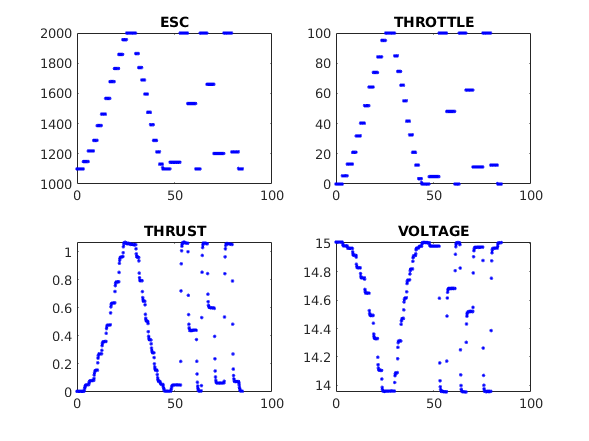

% Overview
figure()
subplot(2,2,1)
plot(time, esc_signal,"b.")
title("ESC")

subplot(2,2,2)
plot(time, throttle,"b.")
title("THROTTLE")

subplot(2,2,3)
plot(time, thrust_kgf, "b.")
title("THRUST")

subplot(2,2,4)
plot(time, voltage_v, "b.")
title("VOLTAGE")

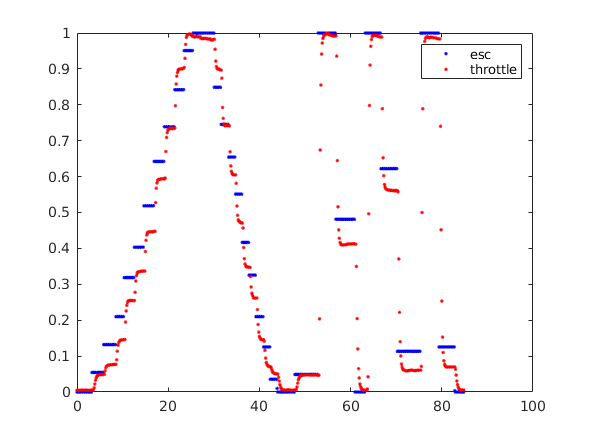

% Thurst and esc signal
normed_esc = esc_signal - 1100;
normed_esc = normed_esc / max(normed_esc);
normed_thrust = thrust_kgf / max(thrust_kgf);

figure()
plot(time, normed_esc,".b")
hold on
plot(time, normed_thrust,".r")
hold off
legend("esc", "throttle")

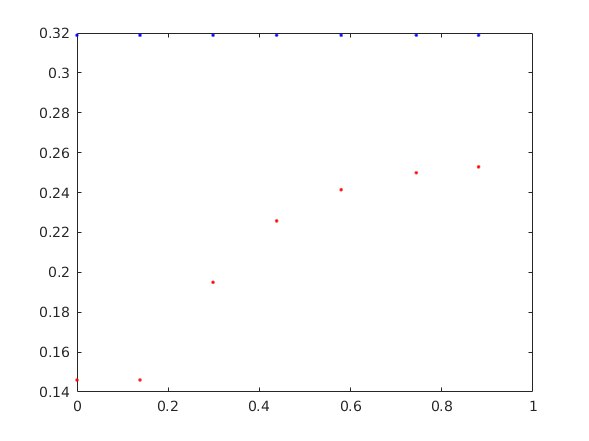

% 1st step input and response
start_i = 70;
end_i = 84;
time_start = time(start_i);
figure()
plot(time(start_i:end_i) - time_start, normed_esc(start_i:end_i), ".b")
hold on
plot(time(start_i:end_i) - time_start, normed_thrust(start_i:end_i), ".r")
hold off
xlim([0, 1])

disp(time(start_i +1)-time(start_i)) % time between 1st and 2nd dot in seconds

    0.1382

